% Parameters
M = 5;    % cart mass
m = 1;    % pendulum mass
l = 2;    % pendulum length
g = 9.81;   % gravity
u = 0;      % control force (N)
b = 10;

x0 = [-4; 0 ; pi+deg2rad(10); 0];

A = [0 1 0 0; 
     0 -b/M -(m*g)/M 0; 
     0 0 0 1; 
     0 -b/(M*l) -((m+M)*g)/(M*l) 0];

B = [0;1/M;0;1/(M*l)];

R = 1e-6;

Q = [1 0 0 0 ; 
    0 1 0 0;
    0 0 10 0;
    0 0 0 1000];

K = lqr(A,B,Q,R)

K = 1.0e+04 *

    0.1000    0.3064    4.1371    2.5553


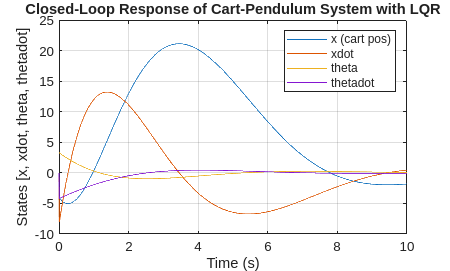

% Closed-loop system
Acl = A - B*K;
sys_cl = ss(Acl, [], eye(4), []);

% Simulate response
t_sim = 0:0.01:10;
[y, t] = initial(sys_cl, x0, t_sim);

% Plot
figure;
plot(t, y);
xlabel('Time (s)');
ylabel('States [x, xdot, theta, thetadot]');
legend('x (cart pos)', 'xdot', 'theta', 'thetadot');
title('Closed-Loop Response of Cart-Pendulum System with LQR');
grid on;


% Eigenvalues
disp('Closed-loop eigenvalues:');

Closed-loop eigenvalues:


disp(eig(Acl));

   1.0e+03 *

  -3.1686 + 0.0000i
  -0.0006 + 0.0000i
  -0.0004 + 0.0006i
  -0.0004 - 0.0006i



eig(A-B*K)

ans = 1.0e+04 *

  -6.3253 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i


t_sim = 0:1:50;

% Simulate the system response using the state-space representation
sys = ss(A, B, eye(4), 0);
[y, t] = lsim(sys, u*ones(size(t_sim)), t_sim, x0);

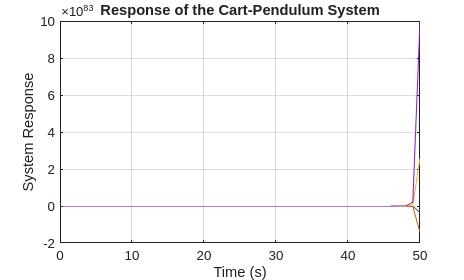

% Plot the system response
figure;
plot(t, y);
xlabel('Time (s)');
ylabel('System Response');
title('Response of the Cart-Pendulum System');
grid on;

Error using lqr (line 42)
Cannot compute the stabilizing Riccati solution S for the LQR design. 
This could be because: 
  * (A,E) has imaginary-axis or unit-circle modes that are not controllable through B, 
  * R is not positive definite, 
  * [Q N;N' R] is indefinite, 
  * The E matrix in the state equation is singular.